folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Optimal_control_theory\lab5\tex\images\";

parallel.gpu.enableCUDAForwardCompatibility(true);
gpuDevice;

A = [0 1; -9 -2];
B = [8; 4];
C = [1 0];
G = eye(2);

W0 = [7 4; 4 5];
V0 = 4;

x0 = [1; 0];
xhat0 = [0; 0];

[P0, ~, ~] = care(A.', C.', G*W0*G.', V0);
Lopt = P0*C.'/V0;

Lnew = [-1; -2];

W4 = [8 3; 3 6];
[P4, ~, ~] = care(A.', C.', G*W4*G.', V0);
L4 = P4*C.'/V0;

Wset = {W0, W0, W4, W0};
Vset = [V0, V0, V0, 6];
Lset = {Lopt, Lnew, L4, Lnew};

errorFiles = {
    'task5_errors.png'
    'task5_errors3.png'
    'task5_W_errors.png'
    'task5_V_errors.png'
};

JFiles = {
    'task5_J.png'
    'task5_J3.png'
    'task5_W_J.png'
    'task5_V_J.png'
};

titles = {
    ''
    '$L=(-1,-2)^T$'
    '$\widetilde{W}$'
    '$\widetilde{V}=6$'
};

N = 1000000;
T = 10;
dt = 0.001;

t = (0:0.01:T)';
step = round(0.01/dt);

Jresults = zeros(4, 1);
Jtheory = zeros(4, 1);

for m = 1:4

    W = Wset{m};
    V = Vset(m);
    L = Lset{m};

    Lw = chol(W, 'lower');

    F = A - L*C;

    if any(real(eig(F)) >= 0)
        error('Наблюдатель в пункте %d неустойчив', m+1);
    end

    H = gpuArray(single([G*Lw, -L*sqrt(V)]));
    Fd = gpuArray(single(eye(2) + dt*F));

    E = repmat(gpuArray(single(x0-xhat0)), 1, N);

    Jgpu = gpuArray.zeros(length(t), 1, 'single');
    e1gpu = gpuArray.zeros(length(t), 1, 'single');
    e2gpu = gpuArray.zeros(length(t), 1, 'single');

    gpurng(42);

    Jgpu(1) = mean(sum(E.^2, 1));
    e1gpu(1) = E(1,1);
    e2gpu(1) = E(2,1);

    tic;

    for k = 1:round(T/dt)

        z = randn(3, N, 'single', 'gpuArray');

        E = Fd*E + sqrt(single(dt))*(H*z);

        if mod(k, step) == 0
            i = k/step + 1;

            Jgpu(i) = mean(sum(E.^2, 1));
            e1gpu(i) = E(1,1);
            e2gpu(i) = E(2,1);
        end
    end

    wait(gpuDevice);
    elapsed = toc;

    J = double(gather(Jgpu));
    e1 = double(gather(e1gpu));
    e2 = double(gather(e2gpu));

    Jresults(m) = J(end);

    D = G*W*G.' + L*V*L.';
    S = lyap(F, D);
    Jtheory(m) = trace(S);

    figure('Color', 'w', 'Position', [100 100 1200 900]);

    subplot(2,1,1);
    plot(t, e1, 'b', 'LineWidth', 0.8);
    grid on;

    if m > 1
        title(titles{m}, 'Interpreter', 'latex');
    end

    xlabel('$t$, c', 'Interpreter', 'latex');
    ylabel('$e_{H1}(t)$', 'Interpreter', 'latex');
    set(gca, 'FontSize', 14, ...
        'TickLabelInterpreter', 'latex');

    subplot(2,1,2);
    plot(t, e2, 'r', 'LineWidth', 0.8);
    grid on;

    if m > 1
        title(titles{m}, 'Interpreter', 'latex');
    end

    xlabel('$t$, c', 'Interpreter', 'latex');
    ylabel('$e_{H2}(t)$', 'Interpreter', 'latex');
    set(gca, 'FontSize', 14, ...
        'TickLabelInterpreter', 'latex');

    exportgraphics(gcf, fullfile(folder, errorFiles{m}), ...
        'Resolution', 600);

    figure('Color', 'w', 'Position', [100 100 1200 700]);

    plot(t, J, 'b', 'LineWidth', 1);
    grid on;

    if m > 1
        title(titles{m}, 'Interpreter', 'latex');
    end

    xlabel('$t$, c', 'Interpreter', 'latex');
    ylabel('$J(t)$', 'Interpreter', 'latex');
    set(gca, 'FontSize', 14, ...
        'TickLabelInterpreter', 'latex');

    exportgraphics(gcf, fullfile(folder, JFiles{m}), ...
        'Resolution', 600);

    clear E z Jgpu e1gpu e2gpu

end


Пункт 2


L = 


    0.6577
   -0.6587



J(10.0) = 15.357372


Jуст = 15.303982


GPU time = 12.54 s



Пункт 3


L = 


    -1
    -2



J(10.0) = 100.739838


Jуст = 100.100000


GPU time = 12.24 s



Пункт 4


L = 


    0.7091
   -0.7486



J(10.0) = 17.307671


Jуст = 17.250813


GPU time = 12.09 s



Пункт 5


L = 


    -1
    -2



J(10.0) = 125.335442


Jуст = 124.500000


GPU time = 12.42 s



fprintf('\nСравнение критериев:\n');


Сравнение критериев:



for m = 1:4
    fprintf('Пункт %d: J(10) = %.6f, Jуст = %.6f\n', ...
        m+1, Jresults(m), Jtheory(m));
end

Пункт 2: J(10) = 15.357372, Jуст = 15.303982
Пункт 3: J(10) = 100.739838, Jуст = 100.100000
Пункт 4: J(10) = 17.307671, Jуст = 17.250813
Пункт 5: J(10) = 125.335442, Jуст = 124.500000


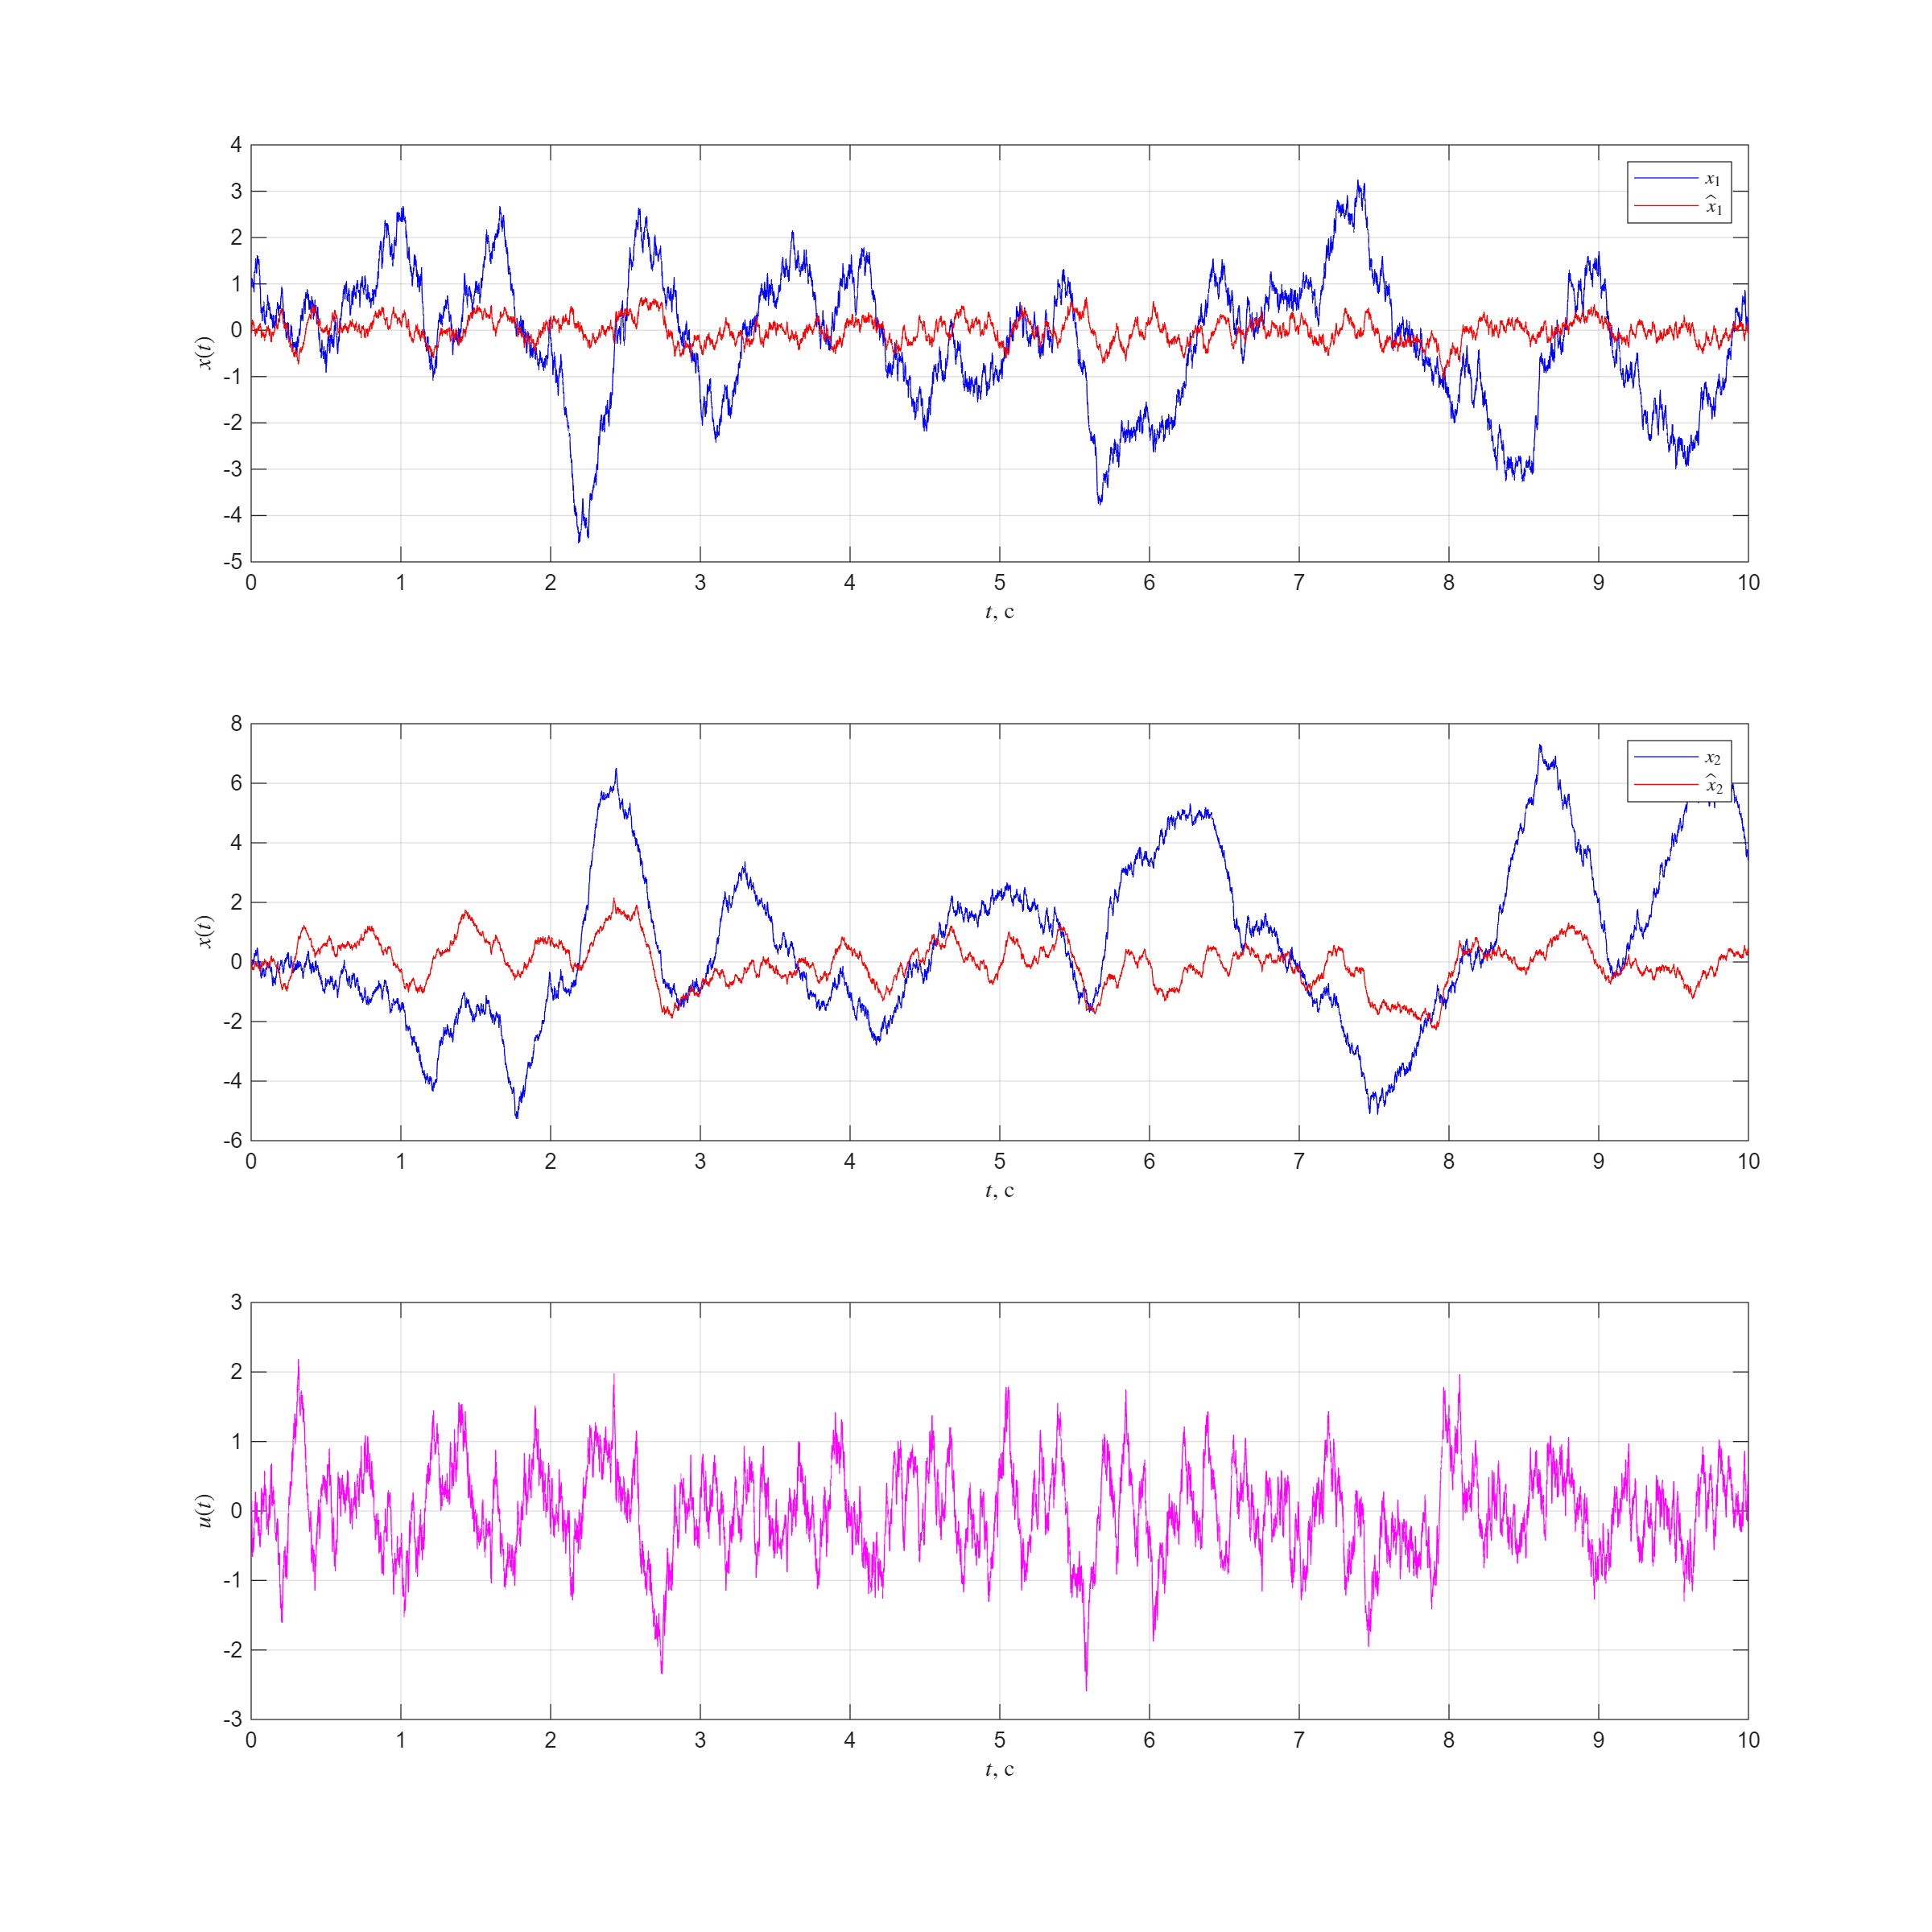

A = [0 1; -9 -2];
B = [8; 4];
C = [1 0];
G = eye(2);

W = [7 4; 4 5];
V = 4;

Q = [1 2.5; 2.5 7];
R = 3;

x0 = [1; 0];
xhat0 = [0; 0];

Bss = [B G];
Css = eye(2);
Dss = zeros(2,3);

Lw = chol(W, 'lower');

[Pobs, ~, ~] = care(A.', C.', G*W*G.', V);
L = Pobs*C.'/V;

[Preg, ~, ~] = care(A, B, Q, R);
K = B.'*Preg/R;

seedW1 = 1001;
seedW2 = 2001;
seedV = 3001;

T = 10;

out = sim('lab56.slx', 'StopTime', num2str(T));

x = out.x_state;
xhat = out.x_est;
u = out.u_cntrl;

figure('Color', 'w', 'Position', [100 100 1200 1200]);

subplot(3,1,1);
plot(x.Time, x.Data(:,1), 'b', ...
     xhat.Time, xhat.Data(:,1), 'r-');
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('$x_1$', '$\hat{x}_1$', 'Interpreter', 'latex');

subplot(3,1,2);
plot(x.Time, x.Data(:,2), 'b', ...
     xhat.Time, xhat.Data(:,2), 'r-');
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('$x_2$', '$\hat{x}_2$', 'Interpreter', 'latex');

subplot(3,1,3);
plot(u.Time, u.Data, color='magenta');
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$u(t)$', 'Interpreter', 'latex');

exportgraphics(gcf, fullfile(folder, 'task5_LQG.png'), ...
    'Resolution', 600);

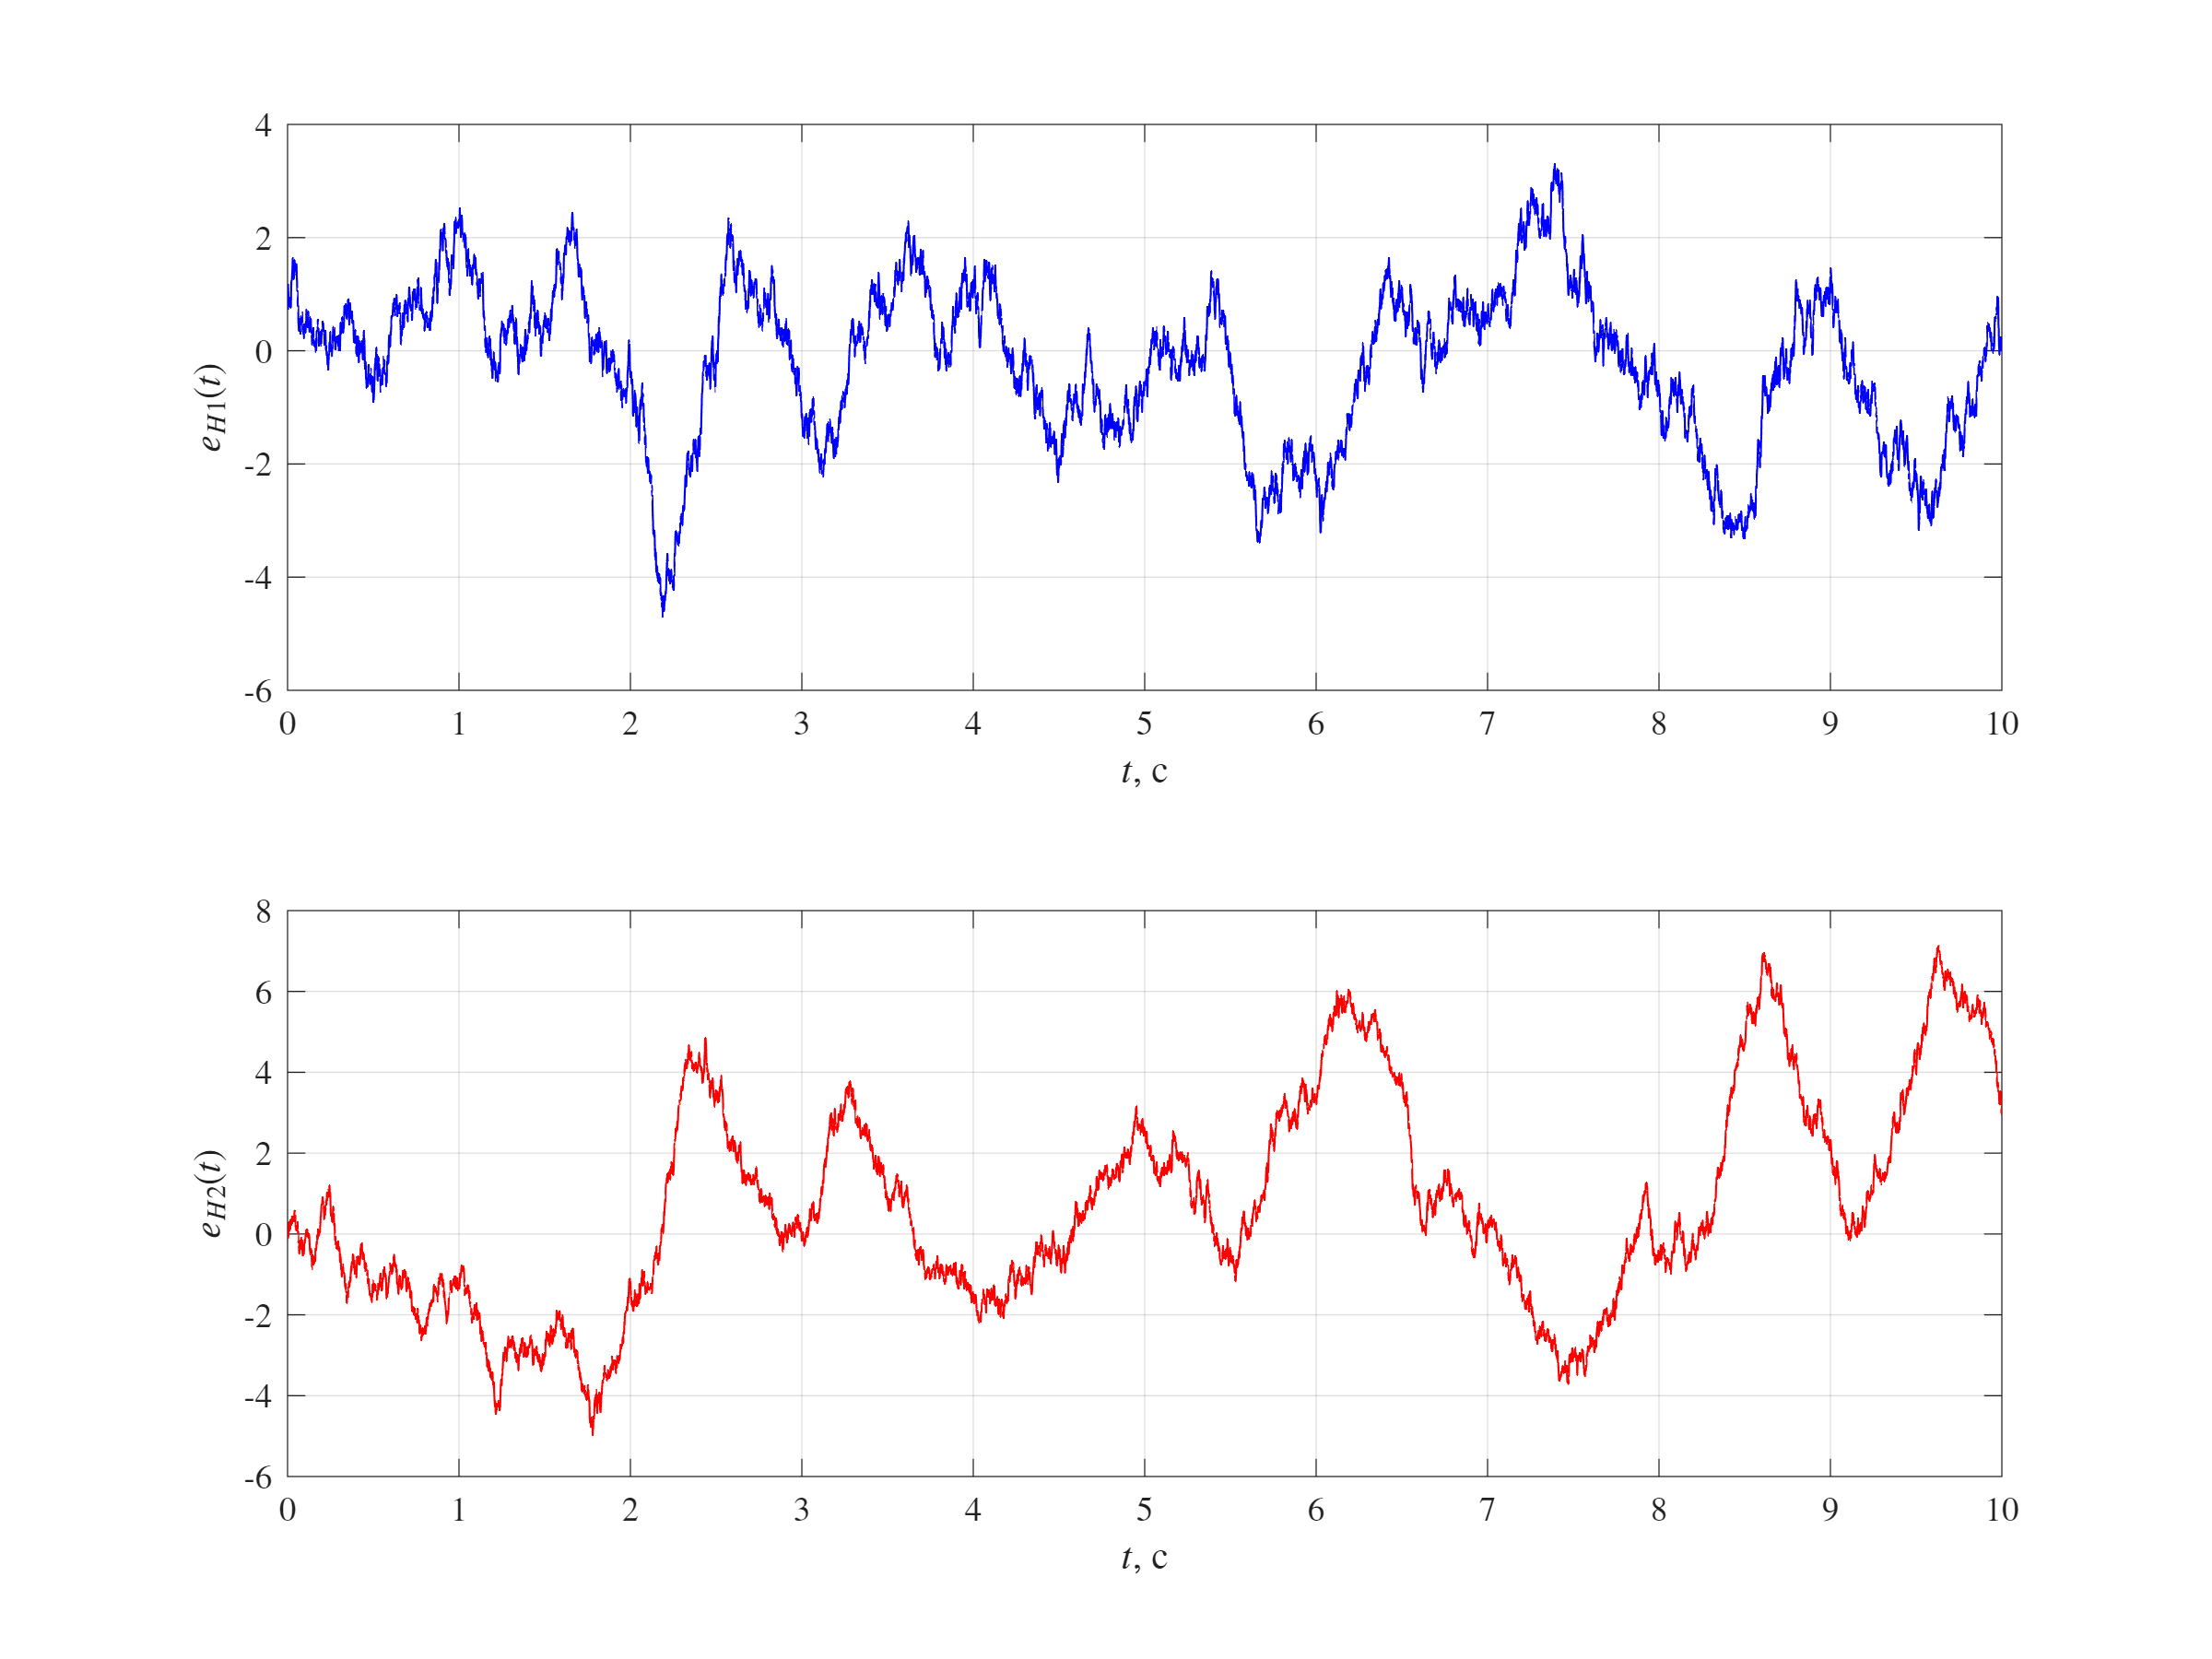


e1 = out.en1;
e2 = out.en2;

figure('Color', 'w', 'Position', [100 100 1200 900]);

subplot(2,1,1);
plot(e1.Time, e1.Data, 'b', 'LineWidth', 0.8);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$e_{H1}(t)$', 'Interpreter', 'latex');
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');

subplot(2,1,2);
plot(e2.Time, e2.Data, 'r', 'LineWidth', 0.8);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$e_{H2}(t)$', 'Interpreter', 'latex');
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');

exportgraphics(gcf, fullfile(folder, 'task5_LQG_errors.png'), ...
    'Resolution', 600)